# Ajuste por mínimos cuadrados

Ver Matlab Grader - Modulo de autoaprendizaje

## Ajuste exponencial

% y=ae^(bx)
xi=2:6;
yi=[3.8 5.8 7.8 8.8 9.8];
% X, Y
Xi=xi
Yi=log(yi)
% Ajuste lineal con polyfit
p=polyfit(Xi,Yi,1)
b=p(1)
ln_a=p(2);
a=exp(ln_a)
% Ecuaciones normales
% Mp=Yi 
M=[Xi' ones(5,1)]
% M'*Mp=M'*Yi
A=M'*M
B=M'* (Yi')
AB=[A B]
% 8=ae^(bx)
x8=log(8/a)/b

## Ajuste de combinación lineal de funciones

% cargar y consultar las variables cargadas
load gong
%whos

% primeros 40 datos
gongClip=y(1:40)

gongClip =    -0.0027
   -0.0045
   -0.0074
   -0.0110
   -0.0128
   -0.0173
   -0.0223
   -0.0223
   -0.0200
   -0.0092


% tiempo
t=[1:40]'/Fs

t =     0.0001
    0.0002
    0.0004
    0.0005
    0.0006
    0.0007
    0.0009
    0.0010
    0.0011
    0.0012



% t: var independiente
% y: var dependiente
% y = a0 + a1*cos(w*t) + b1*sin(w*t)

% frecuencia fundamental
T=2.9722*10^(-3);
w=2*pi/T

w = 2.1140e+03


% Sistema sobredeterminado
A=[ones(40,1) cos(w*t) sin(w*t)]

A =     1.0000    0.9669    0.2552
    1.0000    0.8697    0.4935
    1.0000    0.7150    0.6991
    1.0000    0.5129    0.8584
    1.0000    0.2769    0.9609
    1.0000    0.0225    0.9997
    1.0000   -0.2334    0.9724
    1.0000   -0.4738    0.8806
    1.0000   -0.6829    0.7305
    1.0000   -0.8467    0.5321


B=gongClip

B =    -0.0027
   -0.0045
   -0.0074
   -0.0110
   -0.0128
   -0.0173
   -0.0223
   -0.0223
   -0.0200
   -0.0092


AB=[A B]

AB =     1.0000    0.9669    0.2552   -0.0027
    1.0000    0.8697    0.4935   -0.0045
    1.0000    0.7150    0.6991   -0.0074
    1.0000    0.5129    0.8584   -0.0110
    1.0000    0.2769    0.9609   -0.0128
    1.0000    0.0225    0.9997   -0.0173
    1.0000   -0.2334    0.9724   -0.0223
    1.0000   -0.4738    0.8806   -0.0223
    1.0000   -0.6829    0.7305   -0.0200
    1.0000   -0.8467    0.5321   -0.0092



% Sistema de ecuaciones normales
M=A'*A

M =    40.0000   -3.8243    5.8660
   -3.8243   20.6180    1.4014
    5.8660    1.4014   19.3820


N=A'*B

N =     0.0301
    0.6004
   -0.7041


p = M \ N

p =     0.0101
    0.0338
   -0.0418


a=p(1:2)

a =     0.0101
    0.0338


b=p(3)

b = -0.0418


% Modelo como función de Matlab
f=@(t) a(1)+a(2)*cos(w*t)+b(1)*sin(w*t)

f = function_handle with value:
    @(t)a(1)+a(2)*cos(w*t)+b(1)*sin(w*t)



% Coeficiente de determinación
St=sum((B-mean(B)) .^ 2)

St = 0.0739

Sr=sum((B-f(t)) .^ 2)

Sr = 0.0238

R2=(St-Sr)/St

R2 = 0.6778

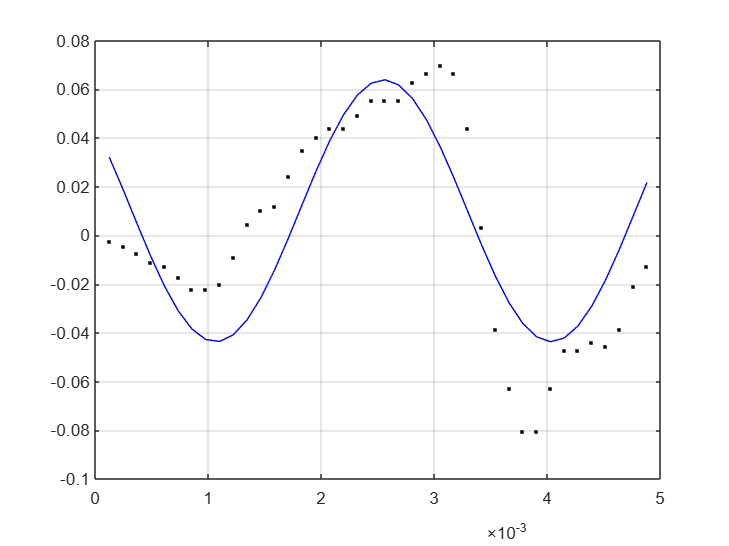


% Gráfico
plot(t,B,'k.')
hold on;
plot(t,f(t),'b-')
grid
hold off;